# 9 Lesen und Schreiben von Dateien, Darstellung von Messwerten (Plots) 

Nachdem wir uns in den letzten Kapiteln die Grundlagen der Programmierung (Ein- und Ausgabe, Kontrollstrukturen und Schleifen sowie Funktionen und Objektorientierung) erarbeitet haben, lernen wir diese Woche eine erste Anwendung kennen, nämlich die Verarbeitung von Messdaten.

- Kapitel 9.1 - Lesen und Schreiben von Dateien

- Kapitel 9.2 - Darstellung von mathematischen Funktionen 

- Kapitel 9.3 - Darstellung von Messwerten

#### Aufgabe 9.1

Bitte lesen Sie - je nach Programmiersprache - folgende Kapitel:

Programmieren mit MATLAB von Ulrich Stein: 

- Kapitel 2.7 Grafik

- Kapitel 2.9 Dateien

## 9.1 Lesen und Schreiben von Dateien

Im Folgenden werden wir immer wieder auf Text-Dateien zugreifen. Legen Sie dazu ein Verzeichnis **week_files09** an. Dabei muss dieses neue Verzeichnis in demselben Verzeichnis liegen wie dieses MATLAB Live Script. Laden Sie dann die Dateien aus dem Ordner week09_files von Moodle herunter und speichern Sie diese lokal auf Ihrer Festplatte in dem Verzeichnis week_files09. 

Als erstes öffnen wir eine Datei und schließen sie dann wieder. Dazu benutzen wir die Funktion `fopen()`. Dabei muss angegeben werden, wie auf die Datei zugegriffen werden soll. Standardmäßig sieht MATLAB drei Varianten des Zugriffs vor:

- lesend "read": `fopen('dateiname', 'r')`

- schreibend "write": `fopen('dateiname', 'w')`

- anhängend "append": `fopen('dateiname', 'a')`

Um die Datei wieder zu schließen, verwendet man die Funktion `fclose().`

datei = fopen('week09_files/textdatei01.txt', 'r');
fclose(datei);

Damit haben wir die Datei geöffnet und wieder geschlossen. Da wir aber nichts weiter mit der Datei gemacht haben, wurde auch nichts angezeigt. Lesen wir nun den Inhalt der Textdatei zeilenweise aus. Bei jedem Aufruf der Funktion `fgetline() `(function get line) wird eine Zeile ausgelesen:

datei = fopen('week09_files/textdatei01.txt', 'r');
zeile = fgetl(datei);
disp(zeile)

Dies ist eine Textdatei.


fclose(datei);

Möchte man mehrere Zeilen einlesen und ausgeben, so müssen wir mehrfach die Funktion `fgetl()` verwenden. Weitere Informationen finden Sie hier: [https://de.mathworks.com/help/matlab/ref/fgetl.html?searchHighlight=fgetl&s_tid=srchtitle](https://de.mathworks.com/help/matlab/ref/fgetl.html?searchHighlight=fgetl&s_tid=srchtitle)

datei = fopen('week09_files/textdatei01.txt', 'r');
zeile = fgetl(datei);
disp(zeile)

Dies ist eine Textdatei.


zeile = fgetl(datei);
disp(zeile)

Und hier die zweite Zeile.


zeile = fgetl(datei);
disp(zeile)
zeile = fgetl(datei);
disp(zeile)

Leerzeilen funktionieren auch, das ist jetzt die 4. Zeile.


fclose(datei);

Und zum Schluss schließen wir die Datei wieder, bitte nicht vergessen!

## 9.2 Darstellung von Funktionen

Zuerst möchten wir mathematische Funktionen darstellen, bevor wir uns an die Visualisierung von Messdaten machen.

### 9.2.1 XY-Diagramme (Plots)

Eine der häufigsten Darstellungen von mathematischen Funktionen ist das xy-Diagramm. Zu jedem x-Wert wird der entsprechende y-Wert (enweder ein Messwert oder ein Funktionswert) als Punkt in ein Koordinatensystem mit x- und y-Achse eingetragen und die Punkte werden mit einer geraden Linie verbunden.

Erzeugen wir uns eine Liste mit x-Werten und dazugehörigen y-Werten als Listen.

x = [-2, -1, 0, 1, 2];
y = [4, 1, 0, 1, 4];

Danach kommt die Funktion zum Zeichen der Werte `plot(x,y):`

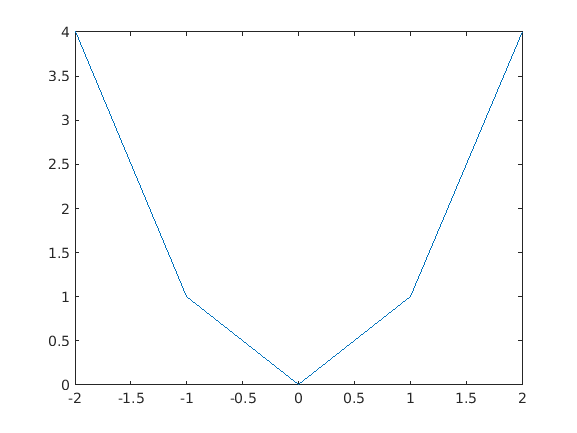

plot(x,y)

Sieht ziemlich krakelig aus. Eigentlich sollte dies eine Parabel werden im Intervall $\left\lbrack -2,2\right\rbrack$ werden. Mit nur 5 Punkten und der Tatsache, dass diese 5 Punkte mit geraden Linien verbunden werden, sieht es etwas unschön aus. Besser wird es mit mehr Punkten, aber die wollen wir jetzt nicht von Hand erzeugen. 

Die Funktion `linspace(a,b, Anzahl)` erzeugt Punkt im Intervall $[a,b]$ je nach eingestellter Anzahl.

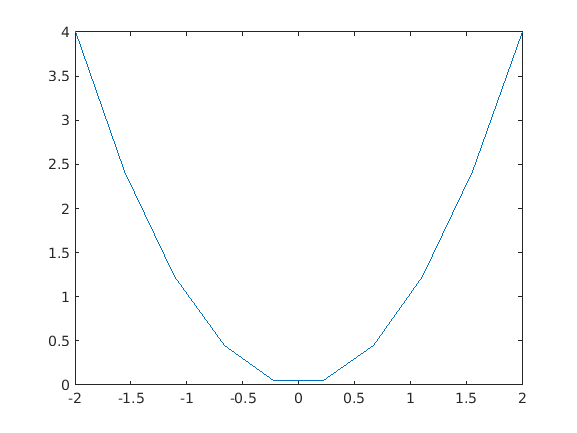

x = linspace(-2, 2, 10);
y = x.^2;

plot(x,y)

Schon besser, aber noch ein paar mehr Punkte wären noch schöner...

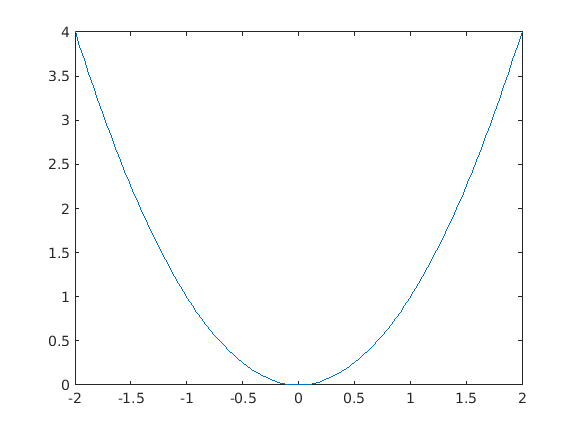

x = linspace(-2, 2, 100);
y = x.^2;

plot(x,y)

#### Aufgabe 9.1 

Bitte plotten Sie folgende Funktionen: 

- $f(x) = 7x + 2$,

- Sinus, 

- Kosinus,

- Exponentialfunktion und 

- Wurzelfunktion.

Verändern Sie auch das Definitionsgebiet der Funktionen, also das Intervall für $x$.

Nächstes Thema, Beschriftungen. Mit den Funktionen `xlabel() `und `ylabel()` beschriften Sie die x- und y-Achse.

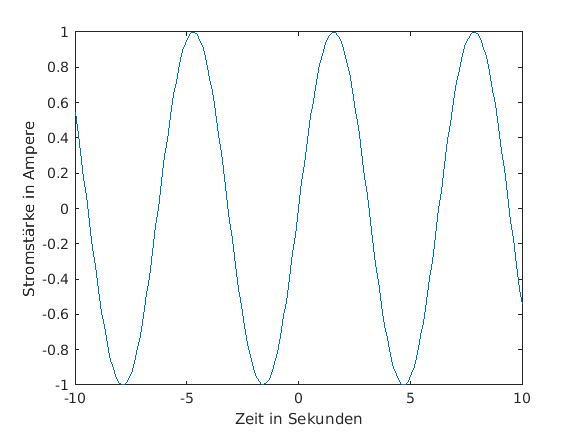

x = linspace(-10,10,200);
y = sin(x);

plot(x,y);
xlabel('Zeit in Sekunden');
ylabel('Stromstärke in Ampere');

Fehlt noch ein Titel für unsere Grafik, das erledigt die Funktion `title()`:

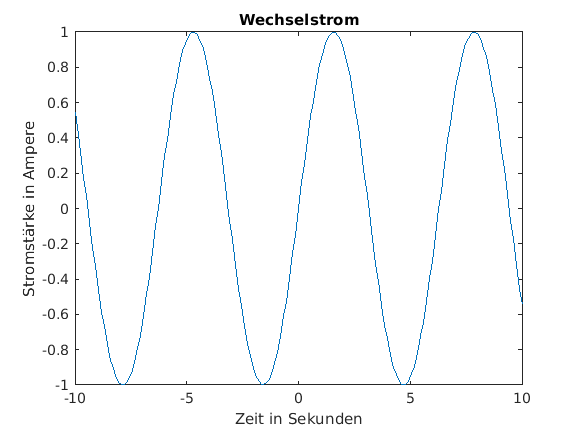

x = linspace(-10,10,200);
y = sin(x);

plot(x,y);
xlabel('Zeit in Sekunden');
ylabel('Stromstärke in Ampere');
title('Wechselstrom');

Zuletzt soll unser Plot mit `saveas() `gespeichert werden. Es stehen mehrere Grafikformate zur Verfügung. Mehr Details finden Sie auf der Internetseite [https://de.mathworks.com/help/matlab/ref/saveas.htmlhttps://de.mathworks.com/help/matlab/ref/saveas.html](https://de.mathworks.com/help/matlab/ref/saveas.html) .

Ein typisches Ausgabeformat ist eine Rastergrafik wie z.B. png. Das erreichen Sie durch den folgenden Funktionsaufruf. Bitte beachten Sie, dass die ID des Grafikobjektes als erstes Argument der `saveas()`-Funktion übergeben müssen. Wenn Sie keine ID gesetzt haben, benutzen Sie einfach `gcf`, (= get current figure), eine Abkürzung für den zuletzt gezeichneten Plot.

x = linspace(-10,10,200);
y = sin(x);

plot(x,y)
xlabel('Zeit in Sekunden')
ylabel('Stromstärke in Ampere')
title('Wechselstrom')
saveas(gcf, 'week09_files/plot_stromstaerke.png')

## 9.2.2 Balkendiagramme

Mit der Funktion `bar()` kann ein Balkendiagramm erstellt werden. Nehmen wir mal an, wir möchten auswerten, wie viele Nutzer/innen in Moodle auf die Jupyter Notebooks zum Download zugegriffen haben:

| Woche | Anzahl Nutzer/innen |

| 2 | 17 |

| 3 | 24 |

| 4 | 73 |

| 5 | 59 |

| 6 | 55 |

| 7 | 57 |

Packen wir das in zwei Vektoren x und y:

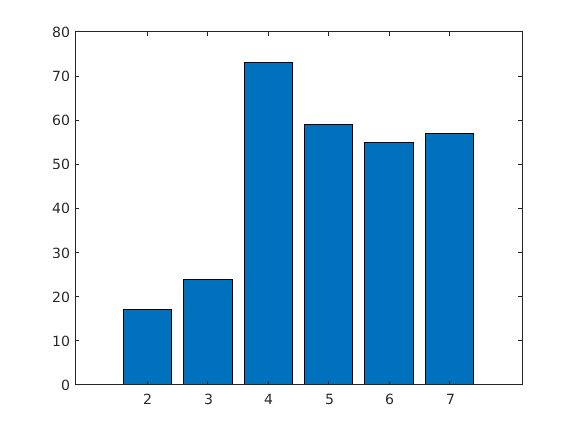

x = [2,3,4,5,6,7];
y = [17, 24, 73, 59, 55, 57];

bar(x,y);

Natürlich funktionieren auch hier die Funktionen `xlabel()`, `ylabel()` und `title()`:

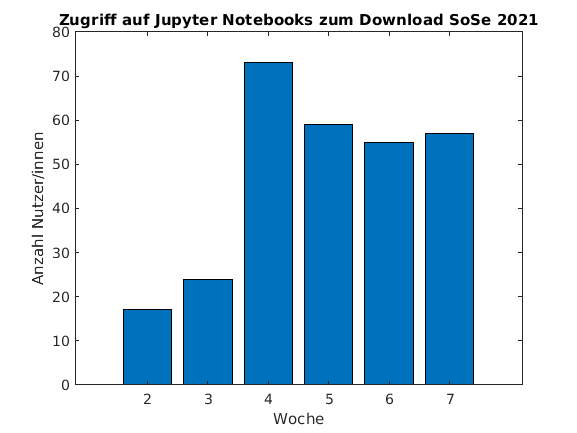

x = [2,3,4,5,6,7];
y = [17, 24, 73, 59, 55, 57];

bar(x,y);
xlabel('Woche');
ylabel('Anzahl Nutzer/innen');
title('Zugriff auf Jupyter Notebooks zum Download SoSe 2021');

#### Aufgabe 9.2

Hier ist eine Tabelle mit den Zugriffszahlen auf das MATLAB Live Script in der Vorlesung angewandte Informatik im Sommersemester 2021. Bitte stellen Sie die Daten als Balkendiagramm inklusive Beschriftungen dar.

|Woche |Anzahl Nutzer/innen|

| 3 | 9  |

| 4 | 17 |

| 5 | 15 |

| 6 | 10 |

| 7 | 11 |

Möchte man zwei oder gar mehrere Funktionen oder Messdaten in einer Grafik darstellen, verwendet man den plot-Befehl mehrfach, setzt aber den Befehl `hold on; `dazwischen:

x  = linspace(-2*pi,2*pi, 200);
y1 = sin(x);
y2 = cos(x);

plot(x,y1);
hold on;
plot(x,y2);

Dann ist es aber auch gut, die Kurven zu beschriften. Dazu verwedet man die Funktion `legend(name1, name2, ...). `

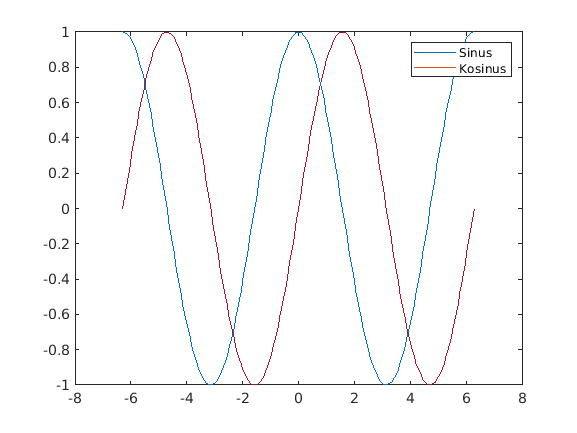

x  = linspace(-2*pi,2*pi, 200);
y1 = sin(x);
y2 = cos(x);

plot(x,y1);
hold on;
plot(x,y2);
legend('Sinus','Kosinus');

#### Aufgabe 9.3

Stellen Sie die Funktionen

- 
$$f1(x) = \sin(x)$$


- 
$$f2(x) = \sin(2x)$$


- 
$$f3(x) = \sin(3x)$$


als xy-Diagramm im Intervall $[-2\pi,2\pi]$ dar und beschriften Sie die Kurven mit einer geeigneten Legende.

**Aufgabe 9.4**

Stellen Sie die Zugriffszahlen auf die Jupyter Notebooks und die MATLAB Live Scripts in einem Balkendiagramm dar. Dabei gibt es ein Problem, welches?

## 9.3 Darstellung von Messwerten

Messwerte werden normalerweise nicht händisch in ein Jupyter Notebook oder ein MATLAB Live Script eingegeben. Meist werden Daten durch einen Sensor in eine Textdatei gespeichert oder in einem Excel-Sheet erfasst. In der Wissenschaft ist es üblich, Messdaten im csv-Format abzuspeichern. Dabei steht csv für **comma separated values**, d.h. in einer Textdatei werden pro Messung eine Zeile verwendet und alle Daten pro Messung werden in diese Zeile durch Komma getrennt geschrieben. In der ersten Zeile stehen sozusagen die Spaltenüberschriften:

` ,Jupyter-Notebook Download,Jupyter-Notebook Cloud,MATLAB Live Script `

`Woche 2,17,19,`

`Woche 3,24,17,9`

`Woche 4,73,34,17`

`Woche 5,59,19,15`

`Woche 6,55,13,10`

`Woche 7,57,28,11`

Als nächstes laden wir unsere Messdaten in das MATLAB Live Script. Laden Sie sich bitte die aktuellen Statistiken zu Covid19 des RKI herunter:

[https://www.rki.de/DE/Content/InfAZ/N/Neuartiges_Coronavirus/Projekte_RKI/Nowcasting_Zahlen_csv.html](https://www.rki.de/DE/Content/InfAZ/N/Neuartiges_Coronavirus/Projekte_RKI/Nowcasting_Zahlen_csv.html)

Alternativ können Sie auch aus dem Verzeichnis `week09_files` die csv-Datei 'Nowcasting_Zahlen_csv.csv' vom 10.06.2021 laden. Der Befehl zum Lesen einer csv-Datei lautet (für mehr Informationen siehe [https://de.mathworks.com/help/matlab/ref/readtable.html?searchHighlight=readtable&s_tid=srchtitle](https://de.mathworks.com/help/matlab/ref/readtable.html?searchHighlight=readtable&s_tid=srchtitle) :

`A=readtable('dateiname.csv')`

Manchmal werden die Daten mit einem Komma `,` getrennt, manchmal - vor allem im deutschsprachigen Raum - auch mit einem Semikolon `;`. Durch Angabe des Separators, also dem Trennzeichen, können wir direkt beim Einlesen schon das richtige einstellen, für viele deutschsprachige Dokumente also 

`A = readtable(dateiname, 'Delimiter',';', 'decimal', ',')`

mit dem Komma als Dezimaltrennzeichen und nicht als Trennzeichen zwischen Spalten.

daten = readtable('week09_files/Nowcasting_Zahlen_csv.csv', 'Delimiter',';', 'decimal', ',');

disp(daten)

                                                          Datum                                                           Sch_tzer_Neuerkrankungen    UG_PI_Neuerkrankungen    OG_PI_Neuerkrankungen    Sch_tzer_Neuerkrankungen_ma4    UG_PI_Neuerkrankungen_ma4    OG_PI_Neuerkrankungen_ma4    Sch_tzer_Reproduktionszahl_R    UG_PI_Reproduktionszahl_R    OG_PI_Reproduktionszahl_R    Sch_tzer_7_Tage_R_Wert    UG_PI_7_Tage_R_Wert    OG_PI_7_Tage_R_Wert
    __________________________________________________________________________________________________________________    ________________________    _____________________    _____________________    ____________________________    _____

Als nächstes wollen wir die Spalte 'Sch_tzer_Neuerkrankungen' plotten. Der Spaltenname sieht etwas merkwürdig aus. Da in der csv-Datei Umlaute sprich 'ä' verwendet wurde, dies aber in MATLAB nicht erlaubt ist, wurde beim Lesen und Importieren der Spaltenname umbenannt.

Wir können direkt auf die Tabelleninhalte zugreifen, wenn wir geschweifte Klammern benutzen. Mit dem Dopplepunkt-Operator `: `und dem Spaltennamen scheniden wir die komplette Spalte aus der Tabelle heraus:

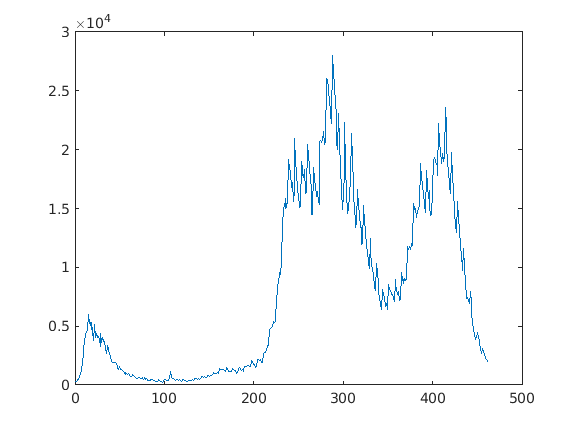

clf;
y = daten{:,'Sch_tzer_Neuerkrankungen'};
plot(y);